images = imageDatastore("data\", "IncludeSubfolders", true, "LabelSource", "foldernames");
countEachLabel(images)
img_classes = {'pos', 'neg_64'};

train_count = 2300
test_count = 100

[images_train, images_test] = splitEachLabel(images, train_count, test_count, 'Include', img_classes);



% Przygotowanie danych treningowych
X_train = zeros(length(images_train.Files), 3780);
Y_train = images_train.Labels;

for i=1:length(images_train.Files)
    if mod(i, 500) == 0
        fprintf("Extracting HOG features i=%d...\n", i);
    end
    I = imread(images_train.Files{i});
    try
        [hog, vis] = extractHOGFeatures(I);
        X_train(i,:) = hog;
    catch ME
        fprintf("Error processing file %s", images_train.Files{i});
        fprintf("Error: %s", ME);
    end
end

% Przygotowanie danych testowych
X_test = zeros(length(images_test.Files), 3780);
Y_test = images_test.Labels;

for i=1:length(images_test.Files)
    if mod(i, 500) == 0
        fprintf("Extracting HOG features i=%d...\n", i);
    end
    I = imread(images_test.Files{i});
    try
        [hog, vis] = extractHOGFeatures(I);
        X_test(i,:) = hog;
    catch ME
        fprintf("Error processing file %s", images_test.Files{i});
        fprintf("Error: %s", ME);
    end
end


% Wytrenowanie klasyfikatora SVM

% model = fitcecoc(X_train, Y_train,'OptimizeHyperparameters','auto', ...
%       'HyperparameterOptimizationOptions', struct('AcquisitionFunctionName','expected-improvement-plus'))
model = fitcsvm(X_train, Y_train);


clear loss;
loss_s = loss(model, X_test, Y_test, 'Lossfun', 'classiferror');
fprintf("loss=%f\n", loss_s);

loss=0.020000


preds = model.predict(X_test);

C = confusionmat(Y_test, preds);

TP = diag(C);         % True positives for each class
FN = sum(C, 2) - TP;  % False negatives for each class

recall = TP ./ (TP + FN)

recall =     0.9800
    0.9800


averageRecall = mean(recall)

averageRecall = 0.9800

scale = 1

count_x = 77

count_y = 34

level=1 count_x=77 count_y=34

out =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0832         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

best_score = 0

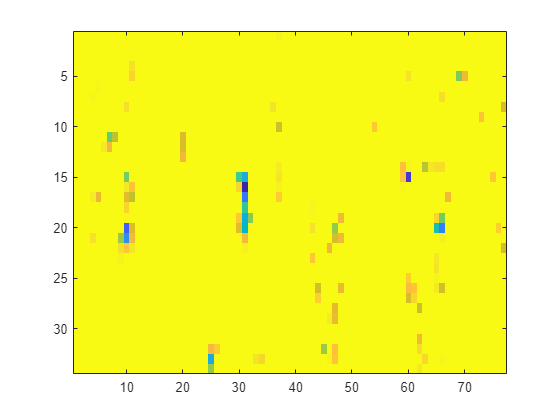

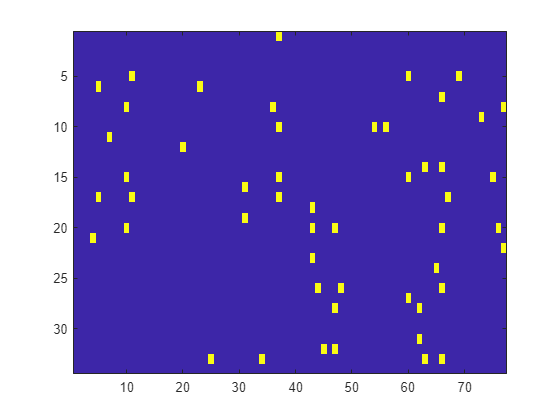

scale = 0.8000

count_x = 60

count_y = 24

level=2 count_x=60 count_y=24

out =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    0.1142         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

best_score = 0

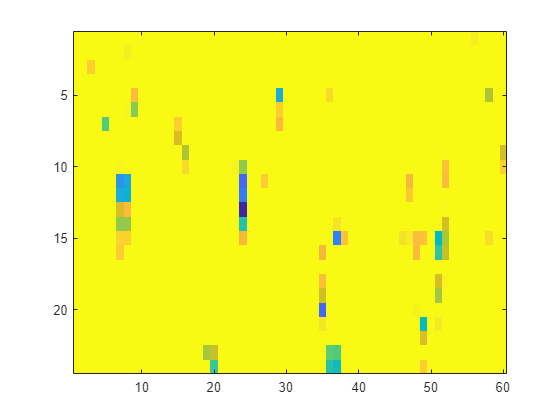

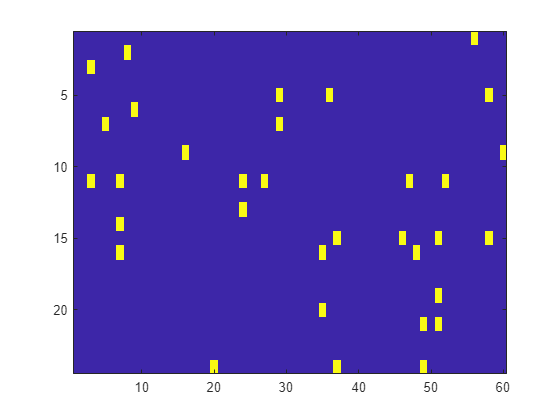

scale = 0.6400

count_x = 46

count_y = 16

level=3 count_x=46 count_y=16

out =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.3692         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0808    0.6860         0         0         0         0    1.0121    1.4445         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.2712    0.1711         0         0         0  

best_score = 0

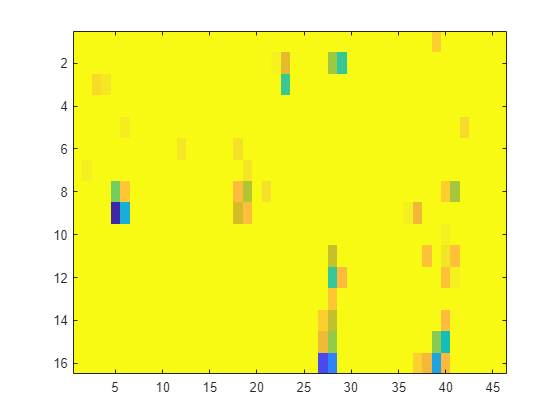

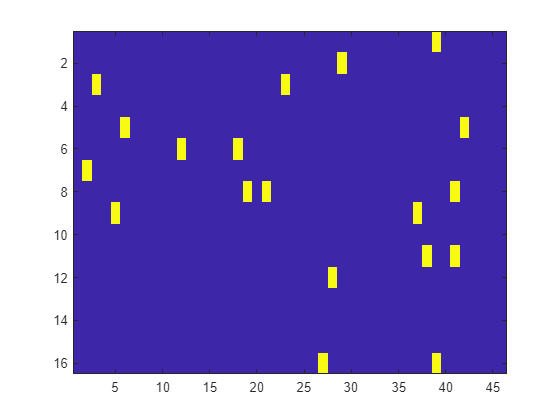

scale = 0.5120

count_x = 35

count_y = 9

level=4 count_x=35 count_y=9

out =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0581         0         0    0.5009         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

best_score = 0

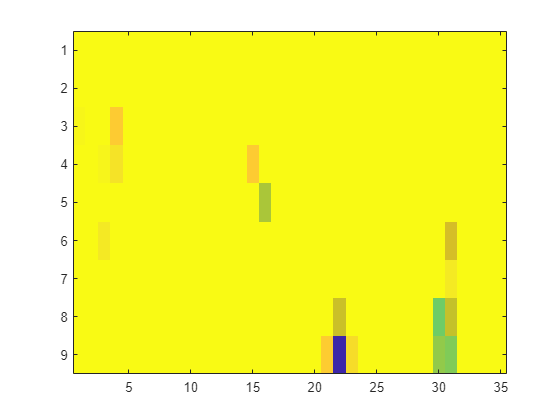

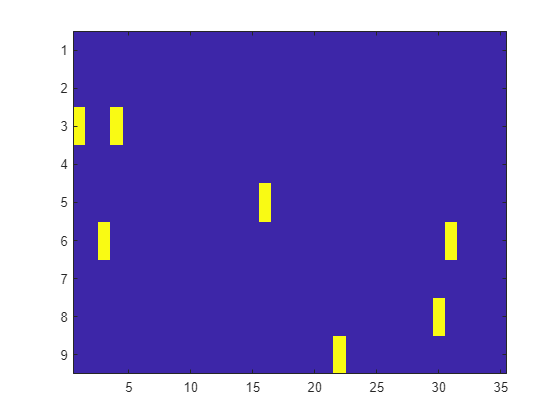

scale = 0.4096

count_x = 27

count_y = 4

level=5 count_x=27 count_y=4

out =     0.4465         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.8533         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

best_score = 0

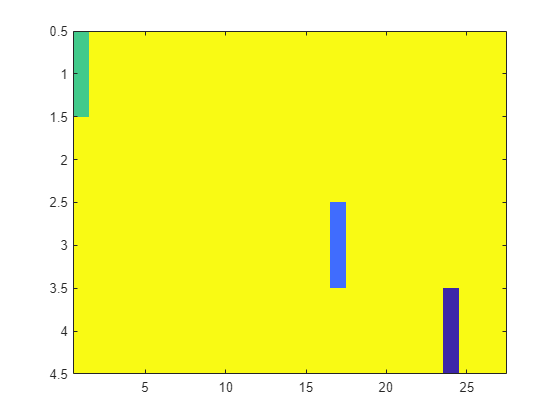

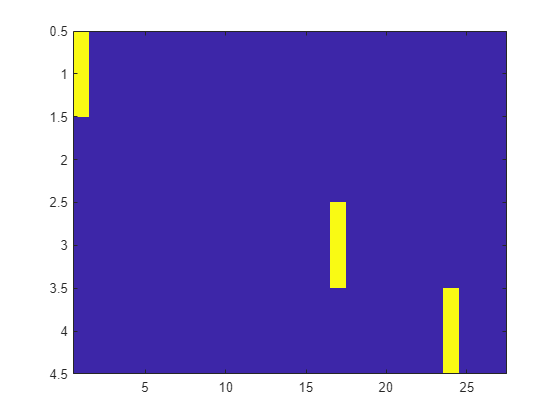


% Weryfikacja klasyfikatora
sx = 64;
sy = 128;
step = 8;

scale_step = 0.8;
levels = 5;

scale = 1.0;
thr = 60;

dets = [];
scores = [];
labels = {};


for k=1:levels

    scale
    cur_img = imresize(It, scale);
    
    w = size(cur_img, 2);
    h = size(cur_img, 1);
    
    count_x = floor((w - sx) / step)
    count_y = floor((h - sy) / step)
    
    fprintf("level=%d count_x=%d count_y=%d", k, count_x, count_y)
    
    out = zeros(count_y, count_x);
    
    for j=0:count_y-1
        for i=0:count_x-1
            %fprintf("level=%d %d/%d (j=%d, i=%d)... \n", k, j*count_x+i, count_y*count_x, j, i);
            x = 1+(i*step);
            y = 1+(j*step);
            sub_img = cur_img(y:y+sy, x:x+sx);
            sub_hog = extractHOGFeatures(sub_img);
            [pred, confidence] = predict(model, sub_hog);
            out(j+1, i+1) = confidence(2);
        end
    end

    out = max(out,0)
    out = (out - min(out(:))) ./ (max(out(:)) - min(out(:)));
    out = 1 - out;
    best_score = min(min(out))
    
    figure;
    imagesc(out)
    figure;
    mins = imregionalmin(out);
    mins(out > thr) = 0;
    imagesc(mins);
    [rs, cs] = find(mins);
    
    for i=1:size(rs)
        x = ((cs(i)-1) * step) / scale + 1;
        y = ((rs(i)-1) * step) / scale + 1;
        w = sx / scale;
        h = sy / scale;
    
        dets = [dets; [x,y,w,h] ];
        scores = [scores, out(rs(i), cs(i))];
        labels{size(dets, 1)} = num2str(out(rs(i), cs(i)), '%.1f');
    end
    
    scale = scale * scale_step;

end

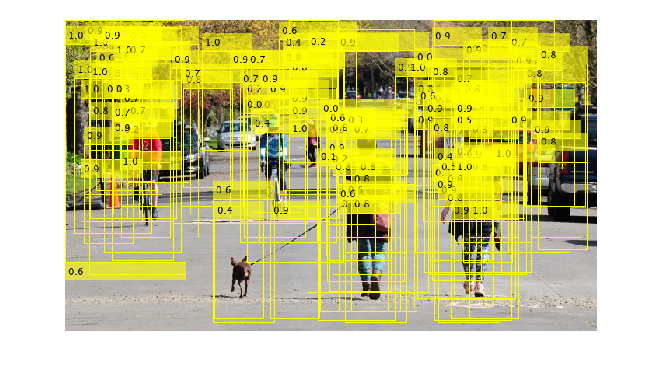

imshow(insertObjectAnnotation(It, 'rectangle', dets, labels));

### Filtracja detekcji i NMS

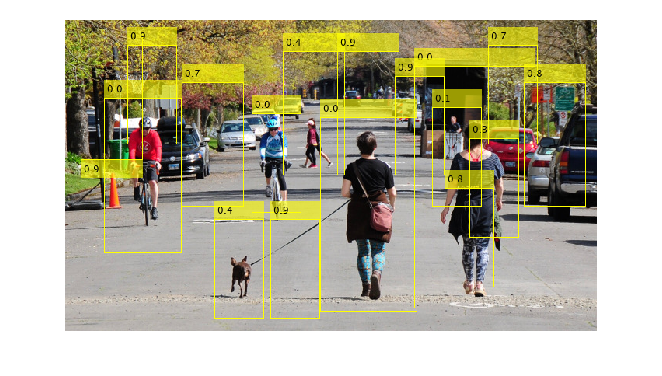

filtered_dets = [];
filtered_scores = [];
tmp_dets = dets;
tmp_scores = scores;
while 1
    [m, i] = min(tmp_scores);
    filtered_dets = [filtered_dets; tmp_dets(i,:)];
    filtered_scores = [filtered_scores, m];
    ratio = bboxOverlapRatio(tmp_dets(i, :), tmp_dets);
    tmp_dets = tmp_dets(ratio < 0.2, :);
    tmp_scores = tmp_scores(ratio < 0.2);
    if size(tmp_dets, 1) < 1
        break
    end
end
cnt = size(filtered_scores, 2);
filtered_lbls = cell(cnt, 1);
for i=1:cnt
    filtered_lbls{i} = num2str(filtered_scores(i), '%.1f');
end
imshow(insertObjectAnnotation(It, "rectangle", filtered_dets, filtered_lbls));

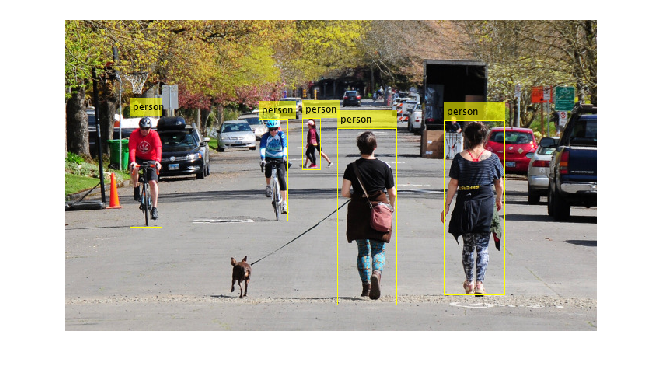

load('gTruth.mat')
gt_rect=gTruth.LabelData.person{1,1};
ann1 = insertObjectAnnotation(It, "rectangle", gt_rect, "person");
imshow(ann1);

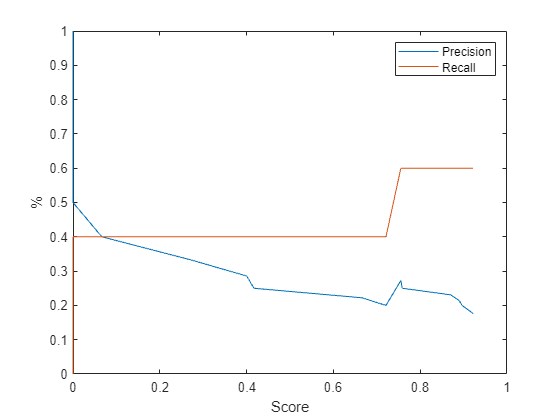

[P, R, sc] = calcpr(filtered_dets, filtered_scores, gt_rect, 0.4);
[P, R, sc] = calcpr(filtered_dets, filtered_scores, gt_rect, 0.4);
figure;
plot(sc, P);
hold on
plot(sc, R);
legend(["Precision", "Recall"]);
xlabel("Score");
ylabel("%");

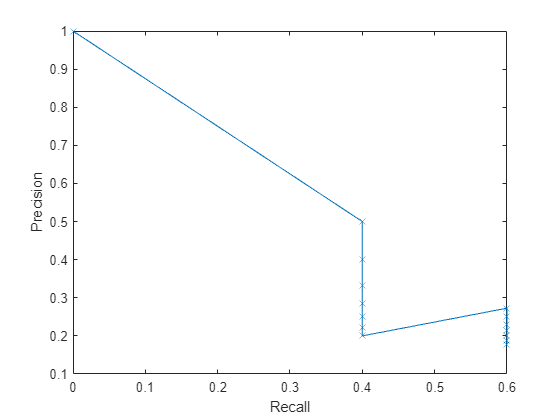


figure;
plot(R, P, 'x-');
xlabel("Recall");
ylabel("Precision");

ap = trapz(R, P)

ap = 0.3473

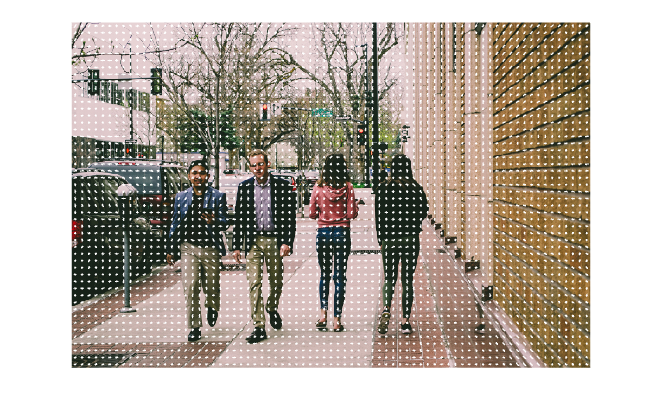


% Example on image people2.jpg
It2 = imread("people_2.jpg");
imshow(It2);
hold on
[hogt2,vist2] = extractHOGFeatures(It2);
plot(vist2)


load('people_2.mat')

Error using load
Unable to find file or directory 'people_2.mat'.

gt_rect=gTruth.LabelData.Person{1,1};
ann1 = insertObjectAnnotation(It2, "rectangle", gt_rect, "person");
imshow(ann1);

[dets, labels, scores] = calcDets(It2, model, 4);

function [P, R, sc] = calcpr(dets, scores, gt_rect, iou)
    cnt = size(scores, 2) + 1;
    P = zeros(cnt, 1);
    R = zeros(cnt, 1);
    sorted_scores = sort(scores);
    
    sorted_scores = [0, sorted_scores];
    sc = sorted_scores;
    
    all_pos = size(gt_rect, 1);
    
    P(1) = 1;
    R(1) = 0;
    
    for ii=2:cnt
        score_thr = sorted_scores(ii);
        selected_dets = dets(scores <= score_thr, :);
        ratio = bboxOverlapRatio(gt_rect, selected_dets);
        [best_overlaps, good_ids] = max(ratio, [], 2);
        best_ids = good_ids(best_overlaps > iou);
        tp = size(best_ids, 1);
        fn = all_pos - tp;
        fp = size(selected_dets, 1) - tp;
        P(ii) = tp / (tp + fp);
        R(ii) = tp / (tp + fn);
    end
end